clear
close all
clc

D = 10;
X_Min = -20;
X_Max = 20;
L = 50; % 每一个温度下的迭代次数
alpha = 0.998; % T_Next = T_Current*h
S0 = 6; % 变异算子
T0 = 100; % 初始温度
T = T0;
error_Thre = 1e-8; % 代价函数阈值
T_Thre = 0.001;
K = 0.6; % Metropolis准则系数

% 迭代次数初始化
iter = 1;
iter_Max = log(T_Thre/T0)/log(alpha);
% iter_Max = T0/T_Thre;


% 参数初始化
Current_X = rand(1, D) .* (X_Max - X_Min) + X_Min;
Current_X_Fitness = Fitness(Current_X);
Pre_X = Current_X;
Pre_X_Fitness = Current_X_Fitness;
Best_X = Current_X;
MinFitness_List = zeros(1,floor(iter_Max)+100);
MinFitness_List(1) = Fitness(Best_X);
Fitness_List = zeros(1,floor(iter_Max)+100);
Fitness_List(1) = MinFitness_List(1);

% 与进度条有关的东西
waitbarinter = iter_Max/100;   
tic
h = waitbar(0, ['已完成:0%   运算中...用时:', num2str(toc)]);

while (MinFitness_List(iter) > error_Thre) && (T > T_Thre)
    iter = iter+1;
    % 1.简易模拟退火
    T = alpha * T;
    % % 2. 经典模拟退火
    % T = T0/log10(iter);
    % % 3. 快速模拟退火
    % T = T0/(iter);


    % 在当前温度T下的迭代
    % 当前温度下最优解的初始化
    Fitness_temp = 0;
    X_temp = zeros(1,D);
    for i = 1:L
        % 随机生成新的解
        N_temp = randn(1,D);
        P_temp = N_temp/sqrt(sum(N_temp.^2));
        Current_X = Pre_X + T*P_temp;
        % 边界限制    防止解过大或过小
        Current_X = BoundaryLimit(Current_X, X_Min, X_Max);
        Current_X_Fitness = Fitness(Current_X);
        % 更新当前温度下的最优解
        if i == 1
            Fitness_temp = Current_X_Fitness;
            X_temp = Current_X;
        else
            if Current_X_Fitness < Fitness_temp
                Fitness_temp = Current_X_Fitness;
                X_temp = Current_X;
            end
        end
        % 判断当前解与最优解以及上一解的大小关系
        if Pre_X_Fitness <= Current_X_Fitness
            % 当前解不如上一次解   Metropolis准则，减小局部最优解的可能
            P = exp(-1 * (Current_X_Fitness - Pre_X_Fitness) / K / T);
            if P > rand
                Pre_X = Current_X;
                Pre_X_Fitness = Current_X_Fitness;
            end

            % 当前解比上一次解好
        else
            Pre_X = Current_X;
            Pre_X_Fitness = Current_X_Fitness;
        end
    end

    % 更新全局最优解
    if MinFitness_List(iter-1) > Fitness_temp
        MinFitness_List(iter) = Fitness_temp;
        Best_X = X_temp;
    else
        MinFitness_List(iter) = MinFitness_List(iter-1);
    end
    % 将每个温度下的最优解都存储起来
    Fitness_List(iter) = Fitness_temp;
    % 进度条
    if mod(iter, waitbarinter) <1
        waitbar(iter / iter_Max, h, ['已完成:' num2str(iter / iter_Max * 100) ...
        '%   运算中...用时:', num2str(toc),'/',num2str(toc/iter * iter_Max)])
    end
end
close(h)

% 结果文字展示
display(['The best solution obtained by SA is : ', num2str(Best_X)]);

The best solution obtained by SA is : -0.020461   -0.012656  -0.0049276    -0.01365    0.013122  -0.0021409    0.021639    0.018917   0.0026335   0.0029471


display(['The best optimal value of the objective funciton found by SA is : ', num2str(MinFitness_List(iter))]);

The best optimal value of the objective funciton found by SA is : 0.0018079


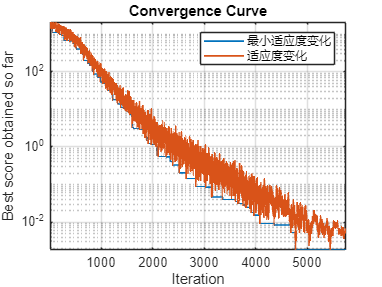


% 结果图像展示
figure
semilogy(MinFitness_List(1:iter),'linewidth',1.2)
hold on
semilogy(Fitness_List(1:iter),'linewidth',1.2)
legend(['最小适应度变化'],['适应度变化'])
title('Convergence Curve')
xlabel('Iteration');
ylabel('Best score obtained so far');
axis tight
grid on
box on



% 目标函数

function result = Fitness(x)
    result = sum(x.^2);
end

% 边界限制函数
function result = BoundaryLimit(X, Min, Max)

    for i_temp = 1:length(X)

        if X(i_temp) > Max
            X(i_temp) = Max;
        end

        if X(i_temp) < Min
            X(i_temp) = Min;
        end

    end

    result = X;
end

